## Controls Systems Textbook Example 10.2

### Reset matlab environment

clearvars
close all
clc
s = tf('s');

### Specs: $e_{ss}\text{ for ramp input}=5\%,\ \text{P.M.}=40\degree$


$$G(s)=\frac{40}{s(s+2)}$$


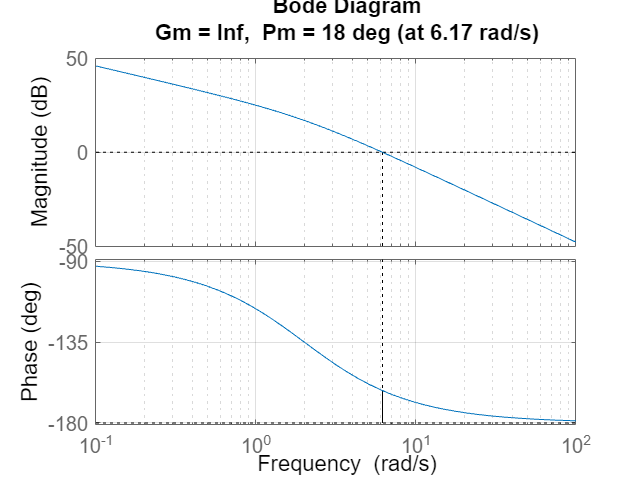

G = 40 / (s*(s+2));   % type 1
margin(G), grid

### A lead compensator for a type-two system


$$K_v=\frac{A}{e_{ss}}=\frac{A}{0.05A}=20\\
\text{We wish to add $22\degree+8\degree=30\degree$ to $\omega'_m$.}\\
\frac{\alpha-1}{\alpha+1}=\sin30\degree=0.5\\
\Rightarrow \alpha=3,\ 10\log_{10}\alpha=4.77\text{dB},\ \omega'_m=8.2\text{ rad/s}$$


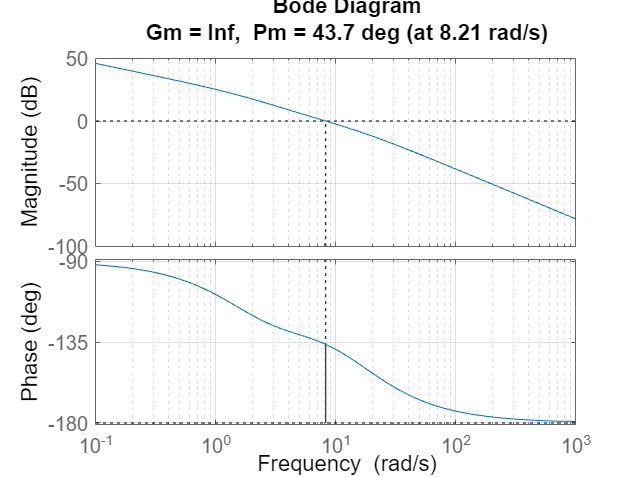

pzratio = 3;
omega_m = 8.2;
p = omega_m * sqrt(pzratio);
z = p / pzratio;
K = pzratio;
G_C = K * (s + z) / (s + p);
L = G_C * G;
T = feedback(L, 1);
margin(L), grid

evalfr(s * L, 10^-10)

ans = 20.0000